syms t w;
f(t,w) = 1 + w/t;
y(t) = t*log(t) + 2*t;

for h=[1/10, 1/20, 1/40]
    [~, y_values] = Exact_Values(h, y);
    [t_values, w_values] = Modified_Euler_Method(h, f);
    [error_values, max_error] = Error(y_values, w_values);
    fprintf('----------------------------------------------------\n');
    fprintf('Modified Euler method with h=1/%d:\n', 1/h);
    fprintf('Approximated values are:\n');
    disp(w_values);
    fprintf('Absolute errors for each values are\n');
    disp(error_values);
    fprintf('Maximum absolute error is: %e\n', max_error)
end

----------------------------------------------------


Modified Euler method with h=1/10:


Approximated values are:


    2.0000    2.3045    2.6182    2.9402    3.2700    3.6069    3.9505    4.3003    4.6561    5.0174    5.3839



Absolute errors for each values are


         0    0.0003    0.0006    0.0008    0.0011    0.0013    0.0015    0.0017    0.0020    0.0022    0.0024



Maximum absolute error is: 2.356042e-03


----------------------------------------------------


Modified Euler method with h=1/20:


Approximated values are:


    2.0000    2.1512    2.3048    2.4606    2.6186    2.7787    2.9409    3.1049    3.2708    3.4385    3.6079    3.7789    3.9516    4.1259    4.3016    4.4789    4.6575    4.8376    5.0190    5.2017    5.3857



Absolute errors for each values are


   1.0e-03 *

         0    0.0392    0.0767    0.1128    0.1475    0.1812    0.2138    0.2456    0.2765    0.3067    0.3363    0.3653    0.3937    0.4217    0.4492    0.4763    0.5031    0.5295    0.5556    0.5814    0.6069



Maximum absolute error is: 6.068784e-04


----------------------------------------------------


Modified Euler method with h=1/40:


Approximated values are:


    2.0000    2.0753    2.1512    2.2277    2.3048    2.3825    2.4607    2.5395    2.6187    2.6986    2.7789    2.8597    2.9410    3.0228    3.1051    3.1878    3.2710    3.3546    3.4387    3.5232    3.6081    3.6935    3.7792    3.8654    3.9519    4.0388    4.1262    4.2139    4.3020    4.3904    4.4792    4.5684    4.6579    4.7478    4.8380    4.9285    5.0194    5.1106    5.2021    5.2940    5.3861



Absolute errors for each values are


   1.0e-03 *

         0    0.0050    0.0100    0.0148    0.0195    0.0242    0.0287    0.0332    0.0375    0.0418    0.0461    0.0503    0.0544    0.0584    0.0624    0.0664    0.0703    0.0741    0.0779    0.0817    0.0854    0.0891    0.0928    0.0964    0.1000    0.1036    0.1071    0.1106    0.1141    0.1175    0.1209    0.1243    0.1277    0.1310    0.1344    0.1377    0.1410    0.1443    0.1475    0.1508    0.1540



Maximum absolute error is: 1.539778e-04


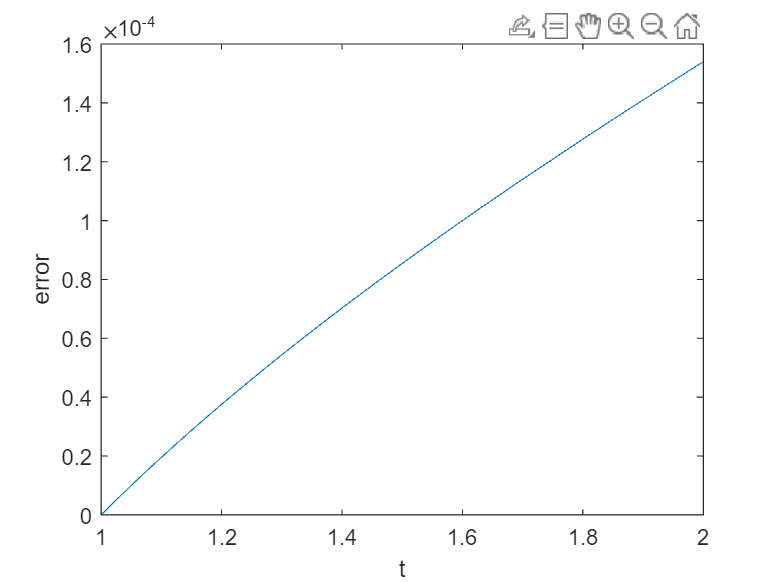


% last t_values and error_values are saved
% they are values associated with h=1/40
plot(t_values, error_values)
xlabel('t');
ylabel('error');

function [t_values, w_values] = Modified_Euler_Method(h, f)
    % for speed, i did preallocation
    numbs = 1/h + 1;
    t_values = 1:h:2;
    w_values = zeros(1, numbs);

    t = 1;
    w = 2;
    w_values(1) = w;
    for i=2:numbs
        w = w + h/2 * (f(t,w) + f(t+h,w+h*f(t,w)));
        w_values(i) = w;
        t = t + h;
    end
end

function [t_values, y_values] = Exact_Values(h, y)
    % for speed, i did preallocation
    numbs = 1/h + 1;
    t_values = 1:h:2;
    y_values = zeros(1, numbs);

    t = 1;
    for i=1:numbs
        y_values(i) = y(t);
        t = t + h;
    end
end

function [error_values, max_error] = Error(exact_values, approx_values)
    error_values = abs(exact_values - approx_values);
    max_error = max(error_values);
end